% Define the file path (change 'your_file_path' to the actual path of your Excel file)
filename = 'C:\Users\azn4e\OneDrive\Desktop\University shit\EELE 489R Capstone 2\ADC_Rawdata.xlsx';

% Load the data from the Excel file
data = readtable(filename);

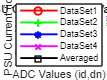

% Extract the variables by converting the table data to arrays using curly braces
id1 = data{1:31, 2};     % PSU Current
Vid_dn1 = data{1:31, 9};  % ADC values
id_dn1 = (Vid_dn1 - 0.5) / 0.8;
%-----------------------------------
id2 = data{35:65, 2};     % PSU Current
Vid_dn2 = data{35:65, 9};  % ADC values
id_dn2 = (Vid_dn2 - 0.5) / 0.8;
%-----------------------------------
id3 = data{69:99, 2};     % PSU Current
Vid_dn3 = data{69:99, 9};  % ADC values
id_dn3 = (Vid_dn3 - 0.5) / 0.8;
%-----------------------------------
id4 = data{103:133, 2};     % PSU Current
Vid_dn4 = data{103:133, 9};  % ADC values
id_dn4 = (Vid_dn4 - 0.5) / 0.8;
%-----------------------------------
% Calculate the averaged Values
ida = (id1 + id2 + id3 + id4) / 4;    % PSU Current
id_dna = (id_dn1 + id_dn2 + id_dn3 + id_dn4) / 4;

% Plot id vs id_dn with different markers and perform linear regression
figure;
hold on; % Hold on to plot multiple datasets

% Plot individual data sets with different markers
plot(id_dn1, id1, 'or-', 'LineWidth',1.5);
plot(id_dn2, id2, '+g-', 'LineWidth', 1.5);
plot(id_dn3, id3, '*b-', 'LineWidth', 1.5);
plot(id_dn4, id4, 'xm-', 'LineWidth', 1.5);
plot(id_dna, ida, 'sk-', 'LineWidth', 1.5); % Averaged values with square markers

% Linear regression and plot the fit line for each dataset
[fit1, gof1] = fit(id_dn1, id1, 'poly1');
[fit2, gof2] = fit(id_dn2, id2, 'poly1');
[fit3, gof3] = fit(id_dn3, id3, 'poly1');
[fit4, gof4] = fit(id_dn4, id4, 'poly1');
[fit_avg, gof_avg] = fit(id_dna, ida, 'poly1');

% % Plot the fit lines and equations
% plot(fit1, 'r-');
% plot(fit2, 'g-');
% plot(fit3, 'b-');
% plot(fit4, 'm-');
% plot(fit_avg, 'k-');

% Define offsets for displaying the equation text
offsetX = .2;%(max(id1) - min(id1)) * 0.1; % 10% of the range to the right of max id
offsetY = -.2;%(max(id_dn1) - min(id_dn1)) * 0.1; % 10% above max id_dn

% Create a function to display the equation text
displayEquationText = @(fitResult, gof, id_dn, id, color, xOffset, yOffset) ...
    text(min(id) + xOffset, max(id_dn) + yOffset, ...
    sprintf('y = %.5fx + %.5f, R^2 = %.5f', coeffvalues(fitResult), gof.rsquare), ...
    'Color', color, 'FontSize', 8);

% Display the equation and R-squared for each fit
displayEquationText(fit1, gof1, id_dn1, id1, 'r', offsetX, offsetY * 4); % Adjust multiplier as needed
displayEquationText(fit2, gof2, id_dn2, id2, 'g', offsetX, offsetY * 3); % Adjust multiplier as needed
displayEquationText(fit3, gof3, id_dn3, id3, 'b', offsetX, offsetY * 2); % Adjust multiplier as needed
displayEquationText(fit4, gof4, id_dn4, id4, 'm', offsetX, offsetY * 1); % Adjust multiplier as needed
displayEquationText(fit_avg, gof_avg, id_dna, ida, 'k', offsetX, offsetY * 0); % Adjust multiplier as needed

% Customize the plot
title('PSU Current vs ADC Values');
xlabel('ADC Values (id,dn)');
ylabel('PSU Current (id)');
legend({'DataSet1', 'DataSet2', 'DataSet3', 'DataSet4', 'Averaged'}, 'Location', 'best');
hold off; % Release the hold on the plot

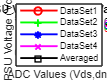

% Extract the variables by converting the table data to arrays using curly braces
Vds1 = data{1:31, 3};     % PSU Current
Vds_dn1 = data{1:31, 10};  % ADC values
Vdsr_dn1 = (Vds_dn1*(5/3));
%-----------------------------------
Vds2 = data{35:65, 3};     % PSU Current
Vds_dn2 = data{35:65, 10};  % ADC values
Vdsr_dn2 = (Vds_dn2 *(5/3));
%-----------------------------------
Vds3 = data{69:99, 3};     % PSU Current
Vds_dn3 = data{69:99, 10};  % ADC values
Vdsr_dn3 = (Vds_dn3*(5/3));
%-----------------------------------
Vds4 = data{103:133, 3};     % PSU Current
Vds_dn4 = data{103:133, 10};  % ADC values
Vdsr_dn4 = (Vds_dn4*(5/3));
%-----------------------------------
% Calculate the averaged Values
Vdsa = (Vds1 + Vds2 + Vds3 + Vds4) / 4;    % PSU Current
Vdsr_dna = (Vdsr_dn1 + Vdsr_dn2 + Vdsr_dn3 + Vdsr_dn4) / 4;

% Plot id vs id_dn with different markers and perform linear regression
figure;
hold on; % Hold on to plot multiple datasets

% Plot individual data sets with different markers
plot(Vdsr_dn1, Vds1, 'or-', 'LineWidth',1.5);
plot(Vdsr_dn2, Vds2, '+g-', 'LineWidth', 1.5);
plot(Vdsr_dn3, Vds3, '*b-', 'LineWidth', 1.5);
plot(Vdsr_dn4, Vds4, 'xm-', 'LineWidth', 1.5);
plot(Vdsr_dna, Vdsa, 'sk-', 'LineWidth', 1.5); % Averaged values with square markers

% Linear regression and plot the fit line for each dataset
[fit1, gof1] = fit(Vdsr_dn1, Vds1, 'poly1');
[fit2, gof2] = fit(Vdsr_dn2, Vds2, 'poly1');
[fit3, gof3] = fit(Vdsr_dn3, Vds3, 'poly1');
[fit4, gof4] = fit(Vdsr_dn4, Vds4, 'poly1');
[fit_avg, gof_avg] = fit(Vdsr_dna, Vdsa, 'poly1');

% Plot the fit lines and equations
% plot(fit1, 'r-');
% plot(fit2, 'g-');
% plot(fit3, 'b-');
% plot(fit4, 'm-');
% plot(fit_avg, 'k-');

% Define offsets for displaying the equation text
offsetX = .2;%(max(id1) - min(id1)) * 0.1; % 10% of the range to the right of max id
offsetY = -.2;%(max(id_dn1) - min(id_dn1)) * 0.1; % 10% above max id_dn

% Create a function to display the equation text
displayEquationText = @(fitResult, gof, Vdsr_dn, Vds, color, xOffset, yOffset) ...
    text(min(Vds) + xOffset, max(Vdsr_dn) + yOffset, ...
    sprintf('y = %.5fx + %.5f, R^2 = %.5f', coeffvalues(fitResult), gof.rsquare), ...
    'Color', color, 'FontSize', 8);

% Display the equation and R-squared for each fit
displayEquationText(fit1, gof1, Vdsr_dn1, Vds1, 'r', offsetX, offsetY * 4); % Adjust multiplier as needed
displayEquationText(fit2, gof2, Vdsr_dn2, Vds2, 'g', offsetX, offsetY * 3); % Adjust multiplier as needed
displayEquationText(fit3, gof3, Vdsr_dn3, Vds3, 'b', offsetX, offsetY * 2); % Adjust multiplier as needed
displayEquationText(fit4, gof4, Vdsr_dn4, Vds4, 'm', offsetX, offsetY * 1); % Adjust multiplier as needed
displayEquationText(fit_avg, gof_avg, Vdsr_dna, Vdsa, 'k', offsetX, offsetY*-1); % Adjust multiplier as needed

% Customize the plot
title('PSU Voltage vs ADC Values');
xlabel('ADC Values (Vds,dn)');
ylabel('PSU Voltage (Vds)');
legend({'DataSet1', 'DataSet2', 'DataSet3', 'DataSet4', 'Averaged'}, 'Location', 'best');
hold off; % Release the hold on the plot

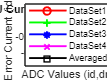


eid1= id1 - id_dn1;
eid2= id2 - id_dn2;
eid3= id3 - id_dn2;
eid4= id4 - id_dn3;
eida= ida - id_dna;
% Plot id vs id_dn with different markers and perform linear regression
figure;
hold on; % Hold on to plot multiple datasets

% Plot individual data sets with different markers
plot(id_dn1, eid1, 'or-', 'LineWidth',1.5);
plot(id_dn2, eid2, '+g-', 'LineWidth', 1.5);
plot(id_dn3, eid3, '*b-', 'LineWidth', 1.5);
plot(id_dn4, eid4, 'xm-', 'LineWidth', 1.5);
plot(id_dna, eida, 'sk-', 'LineWidth', 1.5); % Averaged values with square markers

% Linear regression and plot the fit line for each dataset
[fit1, gof1] = fit(id_dn1, eid1, 'poly1');
[fit2, gof2] = fit(id_dn2, eid2, 'poly1');
[fit3, gof3] = fit(id_dn3, eid3, 'poly1');
[fit4, gof4] = fit(id_dn4, eid4, 'poly1');
[fit_avg, gof_avg] = fit(id_dna, eida, 'poly1');

% % Plot the fit lines and equations
% plot(fit1, 'r-');
% plot(fit2, 'g-');
% plot(fit3, 'b-');
% plot(fit4, 'm-');
% plot(fit_avg, 'k-');

% Define offsets for displaying the equation text
offsetX = 2;%(max(id1) - min(id1)) * 0.1; % 10% of the range to the right of max id
offsetY = -0.01;%(max(id_dn1) - min(id_dn1)) * 0.1; % 10% above max id_dn

% Create a function to display the equation text
displayEquationText = @(fitResult, gof, id_dn, eid, color, xOffset, yOffset) ...
    text(min(id_dn) + xOffset, max(eid) + yOffset, ...
    sprintf('y = %.5fx + %.5f, R^2 = %.5f', coeffvalues(fitResult), gof.rsquare), ...
    'Color', color, 'FontSize', 8);

% Display the equation and R-squared for each fit
displayEquationText(fit1, gof1, id_dn1, eid1, 'r', offsetX, offsetY * 4); % Adjust multiplier as needed
displayEquationText(fit2, gof2, id_dn2, eid2, 'g', offsetX, offsetY * 3); % Adjust multiplier as needed
displayEquationText(fit3, gof3, id_dn3, eid3, 'b', offsetX, offsetY * 2); % Adjust multiplier as needed
displayEquationText(fit4, gof4, id_dn4, eid4, 'm', offsetX, offsetY * 1); % Adjust multiplier as needed
displayEquationText(fit_avg, gof_avg, id_dna, eida, 'k', offsetX, offsetY * 0); % Adjust multiplier as needed

% Customize the plot
title('PSU Current Error vs ADC Values');
xlabel('ADC Values (id,dn)');
ylabel('PSU Error Current (id - id,dn)');
legend({'DataSet1', 'DataSet2', 'DataSet3', 'DataSet4', 'Averaged'}, 'Location', 'best');
hold off; % Release the hold on the plot

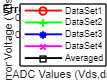

eVds1 = Vds1 - Vdsr_dn1;
eVds2 = Vds2 - Vdsr_dn2;
eVds3 = Vds3 - Vdsr_dn3;
eVds4 = Vds4 - Vdsr_dn4;
eVdsa = Vdsa - Vdsr_dna;
% Plot id vs id_dn with different markers and perform linear regression
figure;
hold on; % Hold on to plot multiple datasets

% Plot individual data sets with different markers
plot(Vdsr_dn1, eVds1, 'or-', 'LineWidth',1.5);
plot(Vdsr_dn2, eVds2, '+g-', 'LineWidth', 1.5);
plot(Vdsr_dn3, eVds3, '*b-', 'LineWidth', 1.5);
plot(Vdsr_dn4, eVds4, 'xm-', 'LineWidth', 1.5);
plot(Vdsr_dna, eVdsa, 'sk-', 'LineWidth', 1.5); % Averaged values with square markers

% Linear regression and plot the fit line for each dataset
[fit1, gof1] = fit(Vdsr_dn1, eVds1, 'poly1');
[fit2, gof2] = fit(Vdsr_dn2, eVds2, 'poly1');
[fit3, gof3] = fit(Vdsr_dn3, eVds3, 'poly1');
[fit4, gof4] = fit(Vdsr_dn4, eVds4, 'poly1');
[fit_avg, gof_avg] = fit(Vdsr_dna, eVdsa, 'poly1');

% Plot the fit lines and equations
% plot(fit1, 'r-');
% plot(fit2, 'g-');
% plot(fit3, 'b-');
% plot(fit4, 'm-');
% plot(fit_avg, 'k-');

% Define offsets for displaying the equation text
offsetX = .2;%(max(id1) - min(id1)) * 0.1; % 10% of the range to the right of max id
offsetY = -.01;%(max(id_dn1) - min(id_dn1)) * 0.1; % 10% above max id_dn

% Create a function to display the equation text
displayEquationText = @(fitResult, gof, Vdsr_dn, eVds, color, xOffset, yOffset) ...
    text(min(eVds) + xOffset, max(eVds) + yOffset, ...
    sprintf('y = %.5fx + %.5f, R^2 = %.5f', coeffvalues(fitResult), gof.rsquare), ...
    'Color', color, 'FontSize', 8);

% Display the equation and R-squared for each fit
displayEquationText(fit1, gof1, Vdsr_dn1, eVds1, 'r', offsetX, offsetY * 4); % Adjust multiplier as needed
displayEquationText(fit2, gof2, Vdsr_dn2, eVds2, 'g', offsetX, offsetY * 3); % Adjust multiplier as needed
displayEquationText(fit3, gof3, Vdsr_dn3, eVds3, 'b', offsetX, offsetY * 2); % Adjust multiplier as needed
displayEquationText(fit4, gof4, Vdsr_dn4, eVds4, 'm', offsetX, offsetY * 1); % Adjust multiplier as needed
displayEquationText(fit_avg, gof_avg, Vdsr_dna, eVdsa, 'k', offsetX, offsetY*-1); % Adjust multiplier as needed

% Customize the plot
title('PSU Error Voltage vs ADC Values');
xlabel('ADC Values (Vds,dn)');
ylabel('PSU Error Voltage (Vds-Vds,dn)');
legend({'DataSet1', 'DataSet2', 'DataSet3', 'DataSet4', 'Averaged'}, 'Location', 'best');
hold off; % Release the hold on the plot

## Case 2 w/ 0-500mA (30 steps)

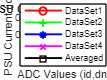

% Extract the variables by converting the table data to arrays using curly braces
id1 = data{139:169, 2};     % PSU Current
Vid_dn1 = data{139:169, 9};  % ADC values
id_dn1 = (Vid_dn1 - 0.5) / 0.8;
%-----------------------------------
id2 = data{173:203, 2};     % PSU Current
Vid_dn2 = data{173:203, 9};  % ADC values
id_dn2 = (Vid_dn2 - 0.5) / 0.8;
%-----------------------------------
id3 = data{207:237, 2};     % PSU Current
Vid_dn3 = data{207:237, 9};  % ADC values
id_dn3 = (Vid_dn3 - 0.5) / 0.8;
%-----------------------------------
id4 = data{241:271, 2};     % PSU Current
Vid_dn4 = data{241:271, 9};  % ADC values
id_dn4 = (Vid_dn4 - 0.5) / 0.8;
%-----------------------------------
% Calculate the averaged Values
ida = (id1 + id2 + id3 + id4) / 4;    % PSU Current
id_dna = (id_dn1 + id_dn2 + id_dn3 + id_dn4) / 4;

% Plot id vs id_dn with different markers and perform linear regression
figure;
hold on; % Hold on to plot multiple datasets

% Plot individual data sets with different markers
plot(id_dn1, id1, 'or-', 'LineWidth',1.5);
plot(id_dn2, id2, '+g-', 'LineWidth', 1.5);
plot(id_dn3, id3, '*b-', 'LineWidth', 1.5);
plot(id_dn4, id4, 'xm-', 'LineWidth', 1.5);
plot(id_dna, ida, 'sk-', 'LineWidth', 1.5); % Averaged values with square markers

% Linear regression and plot the fit line for each dataset
[fit1, gof1] = fit(id_dn1, id1, 'poly1');
[fit2, gof2] = fit(id_dn2, id2, 'poly1');
[fit3, gof3] = fit(id_dn3, id3, 'poly1');
[fit4, gof4] = fit(id_dn4, id4, 'poly1');
[fit_avg, gof_avg] = fit(id_dna, ida, 'poly1');

% % Plot the fit lines and equations
% plot(fit1, 'r-');
% plot(fit2, 'g-');
% plot(fit3, 'b-');
% plot(fit4, 'm-');
% plot(fit_avg, 'k-');

% Define offsets for displaying the equation text
offsetX = 0;%(max(id1) - min(id1)) * 0.1; % 10% of the range to the right of max id
offsetY = -.02;%(max(id_dn1) - min(id_dn1)) * 0.1; % 10% above max id_dn

% Create a function to display the equation text
displayEquationText = @(fitResult, gof, id_dn, id, color, xOffset, yOffset) ...
    text(min(id_dn) + xOffset, max(id) + yOffset, ...
    sprintf('y = %.5fx + %.5f, R^2 = %.5f', coeffvalues(fitResult), gof.rsquare), ...
    'Color', color, 'FontSize', 8);

% Display the equation and R-squared for each fit
displayEquationText(fit1, gof1, id_dn1, id1, 'r', offsetX, offsetY * 4); % Adjust multiplier as needed
displayEquationText(fit2, gof2, id_dn2, id2, 'g', offsetX, offsetY * 3); % Adjust multiplier as needed
displayEquationText(fit3, gof3, id_dn3, id3, 'b', offsetX, offsetY * 2); % Adjust multiplier as needed
displayEquationText(fit4, gof4, id_dn4, id4, 'm', offsetX, offsetY * 1); % Adjust multiplier as needed
displayEquationText(fit_avg, gof_avg, id_dna, ida, 'k', offsetX, offsetY * 0); % Adjust multiplier as needed

% Customize the plot
title('PSU Current vs ADC Values');
xlabel('ADC Values (id,dn)');
ylabel('PSU Current (id)');
legend({'DataSet1', 'DataSet2', 'DataSet3', 'DataSet4', 'Averaged'}, 'Location', 'best');
hold off; % Release the hold on the plot

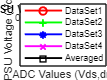

% Extract the variables by converting the table data to arrays using curly braces
Vds1 = data{139:169, 3};     % PSU Current
Vds_dn1 = data{139:169, 10};  % ADC values
Vdsr_dn1 = (Vds_dn1*(5/3));
%-----------------------------------
Vds2 = data{173:203, 3};     % PSU Current
Vds_dn2 = data{173:203, 10};  % ADC values
Vdsr_dn2 = (Vds_dn2 *(5/3));
%-----------------------------------
Vds3 = data{207:237, 3};     % PSU Current
Vds_dn3 = data{207:237, 10};  % ADC values
Vdsr_dn3 = (Vds_dn3*(5/3));
%-----------------------------------
Vds4 = data{241:271, 3};     % PSU Current
Vds_dn4 = data{241:271, 10};  % ADC values
Vdsr_dn4 = (Vds_dn4*(5/3));
%-----------------------------------
% Calculate the averaged Values
Vdsa = (Vds1 + Vds2 + Vds3 + Vds4) / 4;    % PSU Current
Vdsr_dna = (Vdsr_dn1 + Vdsr_dn2 + Vdsr_dn3 + Vdsr_dn4) / 4;

% Plot id vs id_dn with different markers and perform linear regression
figure;
hold on; % Hold on to plot multiple datasets

% Plot individual data sets with different markers
plot(Vdsr_dn1, Vds1, 'or-', 'LineWidth',1.5);
plot(Vdsr_dn2, Vds2, '+g-', 'LineWidth', 1.5);
plot(Vdsr_dn3, Vds3, '*b-', 'LineWidth', 1.5);
plot(Vdsr_dn4, Vds4, 'xm-', 'LineWidth', 1.5);
plot(Vdsr_dna, Vdsa, 'sk-', 'LineWidth', 1.5); % Averaged values with square markers

% Linear regression and plot the fit line for each dataset
[fit1, gof1] = fit(Vdsr_dn1, Vds1, 'poly1');
[fit2, gof2] = fit(Vdsr_dn2, Vds2, 'poly1');
[fit3, gof3] = fit(Vdsr_dn3, Vds3, 'poly1');
[fit4, gof4] = fit(Vdsr_dn4, Vds4, 'poly1');
[fit_avg, gof_avg] = fit(Vdsr_dna, Vdsa, 'poly1');

% Plot the fit lines and equations
% plot(fit1, 'r-');
% plot(fit2, 'g-');
% plot(fit3, 'b-');
% plot(fit4, 'm-');
% plot(fit_avg, 'k-');

% Define offsets for displaying the equation text
offsetX = .01;%(max(id1) - min(id1)) * 0.1; % 10% of the range to the right of max id
offsetY = -.02;%(max(id_dn1) - min(id_dn1)) * 0.1; % 10% above max id_dn

% Create a function to display the equation text
displayEquationText = @(fitResult, gof, Vdsr_dn, Vds, color, xOffset, yOffset) ...
    text(min(Vds) + xOffset, max(Vdsr_dn) + yOffset, ...
    sprintf('y = %.5fx + %.5f, R^2 = %.5f', coeffvalues(fitResult), gof.rsquare), ...
    'Color', color, 'FontSize', 8);

% Display the equation and R-squared for each fit
displayEquationText(fit1, gof1, Vdsr_dn1, Vds1, 'r', offsetX, offsetY * 4); % Adjust multiplier as needed
displayEquationText(fit2, gof2, Vdsr_dn2, Vds2, 'g', offsetX, offsetY * 3); % Adjust multiplier as needed
displayEquationText(fit3, gof3, Vdsr_dn3, Vds3, 'b', offsetX, offsetY * 2); % Adjust multiplier as needed
displayEquationText(fit4, gof4, Vdsr_dn4, Vds4, 'm', offsetX, offsetY * 1); % Adjust multiplier as needed
displayEquationText(fit_avg, gof_avg, Vdsr_dna, Vdsa, 'k', offsetX, offsetY*-1); % Adjust multiplier as needed

% Customize the plot
title('PSU Voltage vs ADC Values');
xlabel('ADC Values (Vds,dn)');
ylabel('PSU Voltage (Vds)');
legend({'DataSet1', 'DataSet2', 'DataSet3', 'DataSet4', 'Averaged'}, 'Location', 'best');
hold off; % Release the hold on the plot

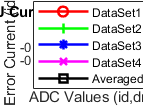


eid1= id1 - id_dn1;
eid2= id2 - id_dn2;
eid3= id3 - id_dn2;
eid4= id4 - id_dn3;
eida= ida - id_dna;
% Plot id vs id_dn with different markers and perform linear regression
figure;
hold on; % Hold on to plot multiple datasets

% Plot individual data sets with different markers
plot(id_dn1, eid1, 'or-', 'LineWidth',1.5);
plot(id_dn2, eid2, '+g-', 'LineWidth', 1.5);
plot(id_dn3, eid3, '*b-', 'LineWidth', 1.5);
plot(id_dn4, eid4, 'xm-', 'LineWidth', 1.5);
plot(id_dna, eida, 'sk-', 'LineWidth', 1.5); % Averaged values with square markers

% Linear regression and plot the fit line for each dataset
[fit1, gof1] = fit(id_dn1, eid1, 'poly1');
[fit2, gof2] = fit(id_dn2, eid2, 'poly1');
[fit3, gof3] = fit(id_dn3, eid3, 'poly1');
[fit4, gof4] = fit(id_dn4, eid4, 'poly1');
[fit_avg, gof_avg] = fit(id_dna, eida, 'poly1');

% % Plot the fit lines and equations
% plot(fit1, 'r-');
% plot(fit2, 'g-');
% plot(fit3, 'b-');
% plot(fit4, 'm-');
% plot(fit_avg, 'k-');

% Define offsets for displaying the equation text
offsetX = 0.2;%(max(id1) - min(id1)) * 0.1; % 10% of the range to the right of max id
offsetY = -0.005;%(max(id_dn1) - min(id_dn1)) * 0.1; % 10% above max id_dn

% Create a function to display the equation text
displayEquationText = @(fitResult, gof, id_dn, eid, color, xOffset, yOffset) ...
    text(min(eid) + xOffset, max((max(id1) - min(id1)) * 0.05) + yOffset, ...
    sprintf('y = %.5fx + %.5f, R^2 = %.5f', coeffvalues(fitResult), gof.rsquare), ...
    'Color', color, 'FontSize', 8);

% Display the equation and R-squared for each fit
displayEquationText(fit1, gof1, id_dn1, eid1, 'r', offsetX, offsetY * 4); % Adjust multiplier as needed
displayEquationText(fit2, gof2, id_dn2, eid2, 'g', offsetX, offsetY * 3); % Adjust multiplier as needed
displayEquationText(fit3, gof3, id_dn3, eid3, 'b', offsetX, offsetY * 2); % Adjust multiplier as needed
displayEquationText(fit4, gof4, id_dn4, eid4, 'm', offsetX, offsetY * 1); % Adjust multiplier as needed
displayEquationText(fit_avg, gof_avg, id_dna, eida, 'k', offsetX, offsetY * 0); % Adjust multiplier as needed

% Customize the plot
title('PSU Current Error vs ADC Values');
xlabel('ADC Values (id,dn)');
ylabel('PSU Error Current (id - id,dn)');
legend({'DataSet1', 'DataSet2', 'DataSet3', 'DataSet4', 'Averaged'}, 'Location', 'best');
hold off; % Release the hold on the plot

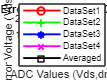

eVds1 = Vds1 - Vdsr_dn1;
eVds2 = Vds2 - Vdsr_dn2;
eVds3 = Vds3 - Vdsr_dn3;
eVds4 = Vds4 - Vdsr_dn4;
eVdsa = Vdsa - Vdsr_dna;
% Plot id vs id_dn with different markers and perform linear regression
figure;
hold on; % Hold on to plot multiple datasets

% Plot individual data sets with different markers
plot(Vdsr_dn1, eVds1, 'or-', 'LineWidth',1.5);
plot(Vdsr_dn2, eVds2, '+g-', 'LineWidth', 1.5);
plot(Vdsr_dn3, eVds3, '*b-', 'LineWidth', 1.5);
plot(Vdsr_dn4, eVds4, 'xm-', 'LineWidth', 1.5);
plot(Vdsr_dna, eVdsa, 'sk-', 'LineWidth', 1.5); % Averaged values with square markers

% Linear regression and plot the fit line for each dataset
[fit1, gof1] = fit(Vdsr_dn1, eVds1, 'poly1');
[fit2, gof2] = fit(Vdsr_dn2, eVds2, 'poly1');
[fit3, gof3] = fit(Vdsr_dn3, eVds3, 'poly1');
[fit4, gof4] = fit(Vdsr_dn4, eVds4, 'poly1');
[fit_avg, gof_avg] = fit(Vdsr_dna, eVdsa, 'poly1');

% Plot the fit lines and equations
% plot(fit1, 'r-');
% plot(fit2, 'g-');
% plot(fit3, 'b-');
% plot(fit4, 'm-');
% plot(fit_avg, 'k-');

% Define offsets for displaying the equation text
offsetX = .02;%(max(id1) - min(id1)) * 0.1; % 10% of the range to the right of max id
offsetY = -.0015;%(max(id_dn1) - min(id_dn1)) * 0.1; % 10% above max id_dn

% Create a function to display the equation text
displayEquationText = @(fitResult, gof, Vdsr_dn, eVds, color, xOffset, yOffset) ...
    text(min(eVds) + xOffset, max(eVds) + yOffset, ...
    sprintf('y = %.5fx + %.5f, R^2 = %.5f', coeffvalues(fitResult), gof.rsquare), ...
    'Color', color, 'FontSize', 8);

% Display the equation and R-squared for each fit
displayEquationText(fit1, gof1, Vdsr_dn1, eVds1, 'r', offsetX, offsetY * 4); % Adjust multiplier as needed
displayEquationText(fit2, gof2, Vdsr_dn2, eVds2, 'g', offsetX, offsetY * 3); % Adjust multiplier as needed
displayEquationText(fit3, gof3, Vdsr_dn3, eVds3, 'b', offsetX, offsetY * 2); % Adjust multiplier as needed
displayEquationText(fit4, gof4, Vdsr_dn4, eVds4, 'm', offsetX, offsetY * 1); % Adjust multiplier as needed
displayEquationText(fit_avg, gof_avg, Vdsr_dna, eVdsa, 'k', offsetX, offsetY*-1); % Adjust multiplier as needed

% Customize the plot
title('PSU Error Voltage vs ADC Values');
xlabel('ADC Values (Vds,dn)');
ylabel('PSU Error Voltage (Vds-Vds,dn)');
legend({'DataSet1', 'DataSet2', 'DataSet3', 'DataSet4', 'Averaged'}, 'Location', 'best');
hold off; % Release the hold on the plot